
rosshutdown;
rosinit;

The value of the ROS_MASTER_URI environment variable, http://localhost:11311, will be used to connect to the ROS master.
The value of the ROS_HOSTNAME environment variable, localhost, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_74915 with NodeURI http://localhost:33533/


clc
c=[];
% [cmdpub,cmdmsg] = rospublisher('/cmd_vel','geometry_msgs/Twist');
[cmdpub,cmdmsg] = rospublisher('PDR_position','geometry_msgs/Point');
% sub = rossubscriber('goal_achieved','std_msgs/Bool');
data=[];c=zeros(1,2);

% rpy=rpy(686:1079,:);
turn_init= 0.0873; %mean(rpy(1:10,2));
% turn_init = -90 * pi / 180 ;
RotMat  = [ cos( turn_init )   -sin( turn_init ) ;
    sin( turn_init )   cos( turn_init )   ]  ;


for i = 1:length(trajectory)
    %     boolsub = receive(sub);
    
    %     cmdmsg.Z = 0;
    %     %     cmdmsg.Y = PositionY(i,1);
    %     %     cmdmsg.X = PositionX(i,1);
    %     cmdmsg.Y = trajectory(i,2);
    %     cmdmsg.X = -trajectory(i,3);
    %     fprintf('working...\r\n');
    %     send(cmdpub,cmdmsg)
    
    %     if i > 2 && boolsub.Data == 1
    
    
    %     cmdmsg.Y = PositionY(i,1);
    %     cmdmsg.X = PositionX(i,1);
    
%     data=[PositionX(i,1),PositionY(i,1)];%*RotMat;
     data=[trajectory(i,2),trajectory(i,3)];%*RotMat;
%         data=[PDRPOS(i,1),PDRPOS(i,2)]*RotMat;
    cmdmsg.X = data(1);
    cmdmsg.Y = data(2);
    cmdmsg.Z = 0;
    fprintf('working...\r\n');
    send(cmdpub,cmdmsg)
    
    %              cmdpause = (PVdata(i,3) - PVdata(i,1))/50;
%     cmdpause = (peakdata(i,1) - peakdata(i-1,1))/50;
    pause(1.5)
    %     end
    
    c=[c;cmdmsg.X,cmdmsg.Y];
    
end

working...
working...
working...
working...
working...
working...
working...
working...
working...



fprintf('end.\r\n')

end.


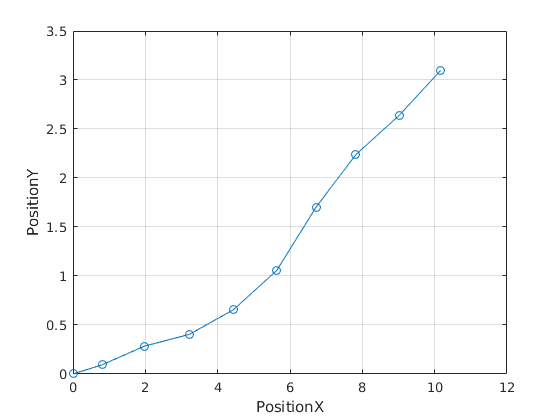

% cmdmsg.X = 0;
% cmdmsg.Y = 0;
% cmdmsg.Z = 0;
% send(cmdpub,cmdmsg)

plot(c(:,1),c(:,2),'o-'),grid on
xlabel('PositionX'); ylabel('PositionY');